# Sim 3 Coupled Tank System

h1 = 0 % cm

h1 = 0

h2 = 0 % cm

h2 = 0

g = 981 % cm/s^2

g = 981

d = 4.45 % cm

d = 4.4500

A_1 = (pi*d^2)/4 % cm^2

A_1 = 15.5528

A_2 = A_1 % cm^2

A_2 = 15.5528

d_or = 0.48 % cm

d_or = 0.4800

A_b = (pi*d_or^2)/4 % cm^2

A_b = 0.1810

A_e = A_b % cm^2

A_e = 0.1810

c_1 = A_b*sqrt(2*g)

c_1 = 8.0153

c_2 = A_e*sqrt(2*g)

c_2 = 8.0153

h_10 = 20 % cm

h_10 = 20

h_20 = 20 % cm

h_20 = 20

q_i0 = c_1*sqrt(h_10)

q_i0 = 35.8457


% h_10 = 10 % cm
% h_20 = 10 % cm
% q_i0 = c_1*sqrt(h_10)

A = [ -(c_1/A_1)*(1/2)*(1/sqrt(h_10)) 0; (c_1/A_2)*(1/2)*(1/sqrt(h_10)) -(c_2/A_2)*(1/2)*(1/sqrt(h_20))]

A =    -0.0576         0
    0.0576   -0.0576


B = [1/A_1; 0];

e_v = eig(A)

e_v =    -0.0576
   -0.0576



con_mat = ctrb(A,B)

con_mat =     0.0643   -0.0037
         0    0.0037


r_con = rank(con_mat)

r_con = 2

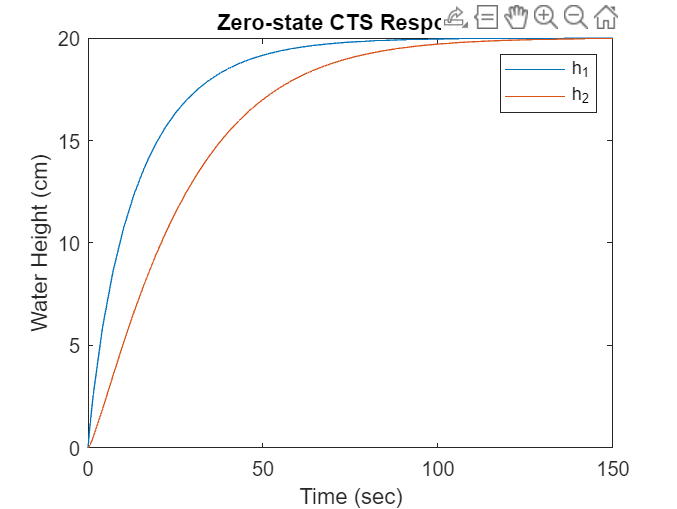

ICs = 0;

out = sim('CTS_Simulink', 150);

figure
plot(out.h_1.Time, out.h_1.Data)
hold on
plot(out.h_2.Time, out.h_2.Data)
title("Zero-state CTS Response")
xlabel("Time (sec)")
ylabel("Water Height (cm)")
legend("h_1", "h_2")

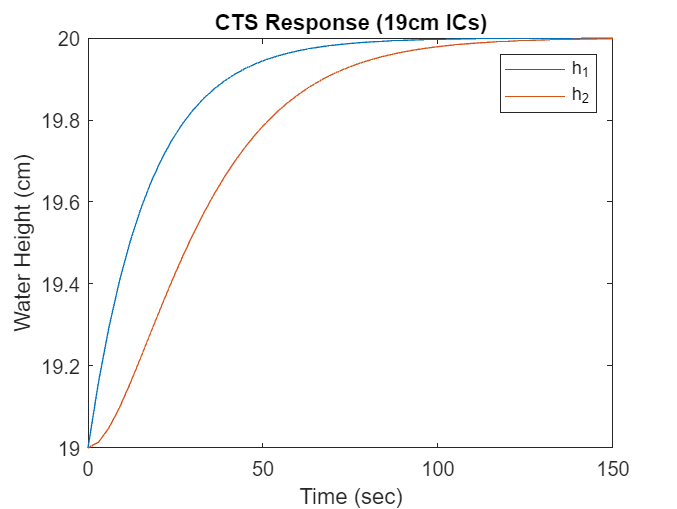

ICs = 19;

out = sim('CTS_Simulink', 150);

figure
plot(out.h_1.Time, out.h_1.Data)
hold on
plot(out.h_2.Time, out.h_2.Data)
title("CTS Response (19cm ICs)")
xlabel("Time (sec)")
ylabel("Water Height (cm)")
legend("h_1", "h_2")